t = 1:5;
s = t;
% by cols: 6 locations, by rows: 5 time
X = [1.0095,0.0095,0,0,0,0;0.9634,1.9649,0.0015,0,0,0;0,0.0001,1.0006,0.0005,0,0;0,0,0.0002,1.8680,0.8678,0;0,0,0,0.0362,1.1570,0.1207;]

X =     1.0095    0.0095         0         0         0         0
    0.9634    1.9649    0.0015         0         0         0
         0    0.0001    1.0006    0.0005         0         0
         0         0    0.0002    1.8680    0.8678         0
         0         0         0    0.0362    1.1570    0.1207


P = X';%6*5
V= P(1:5,:);
b = V;
dX = V;

w0 = P(1,:);
O = P(1:4,:);
D = P(2:5,:);
M = 6;
const = 0.57721;
Sum = 100000;
%fix beta and change alpha, c = mu - beta*log(-log(p))+const
betah = 0.1:0.8; %high-noise
betal = 1:30; %low-noise
beta = 0.5 %simulation

beta = 0.5000

c = 0.6290

c = 1.3940

c = 1.1718

c = 1.0509

c = 0.9737

c = 0.6195

c = 0.6202

c = 0.9240

c = 0.8533

c = 0.8091

c = 0.6195

c = 0.6195

c = 0.6196

c = 1.0305

c = 0.9624

c = 0.6195

c = 0.6195

c = 0.6195

c = 0.8238

c = 0.9817

c = 1.4084

c = 1.0629

c = 0.9287

c = 0.8569

c = 0.8121

c = 0.6195

c = 0.6195

c = 0.9237

c = 0.8530

c = 0.8089

c = 0.6195

c = 0.6195

c = 0.6195

c = 1.0304

c = 1.0912

c = 0.6195

c = 0.6195

c = 0.6195

c = 0.6285

c = 0.8429

c = 1.4084

c = 1.0629

c = 0.9287

c = 0.8569

c = 0.8121

c = 0.6290

c = 1.6971

c = 1.3871

c = 1.2239

c = 1.1198

c = 0.6195

c = 0.6195

c = 0.6195

c = 1.0304

c = 1.0912

c = 0.6195

c = 0.6195

c = 0.6195

c = 0.6285

c = 0.8429

c = 1.4084

c = 1.0629

c = 0.9287

c = 0.8569

c = 0.8121

c = 0.6290

c = 1.6971

c = 1.3871

c = 1.2239

c = 1.1198

c = 0.6195

c = 0.6195

c = 0.9237

c = 0.8530

c = 0.8089

c = 0.6195

c = 0.6195

c = 0.6195

c = 0.6285

c = 0.8429

c = 1.4084

c = 1.0629

c = 0.9287

c = 0.8569

c = 0.8121

c = 0.6290

c = 1.6971

c = 1.3871

c = 1.2239

c = 1.1198

c = 0.6195

c = 0.6195

c = 0.9237

c = 0.8530

c = 0.8089

c = 0.6195

c = 0.6195

c = 0.6195

c = 1.0304

c = 1.0912

alpha = 0.5000

Xhat =     1.0095    0.3641       NaN    0.0219         0    0.0000
    0.9634    0.6358         0    0.0001         0         0
         0    0.0000         0    0.1776         0         0
         0         0         0    0.6367         0    1.0000
         0    0.0000         0    0.1637       NaN    0.0000


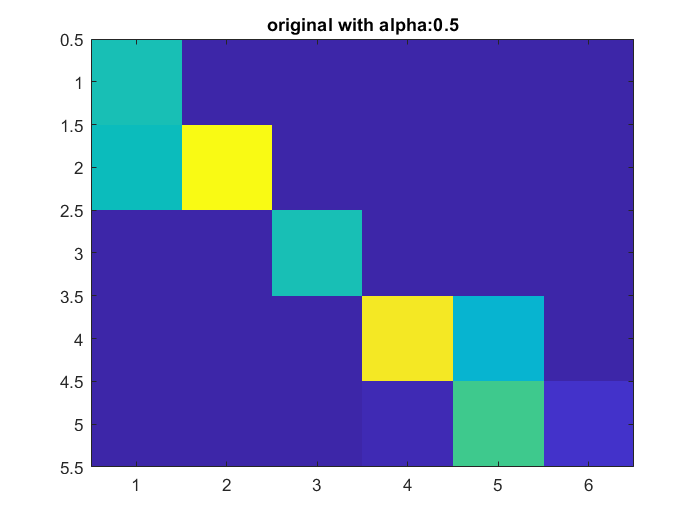

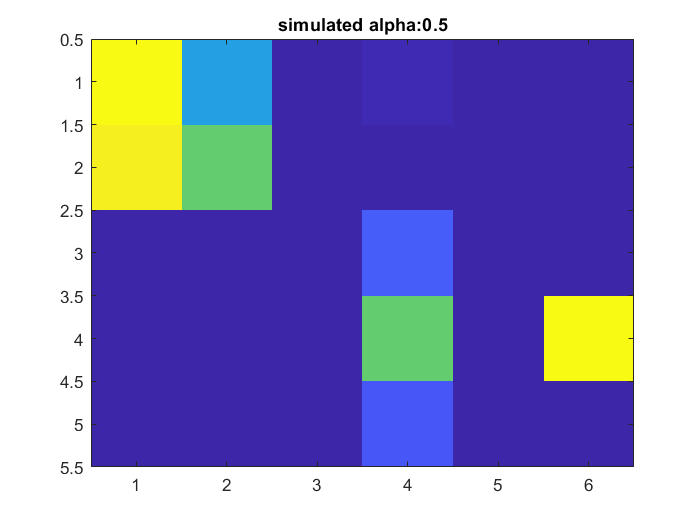

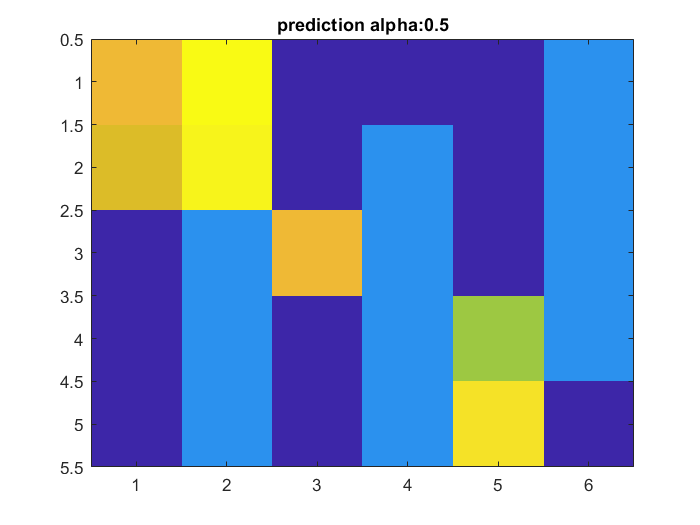

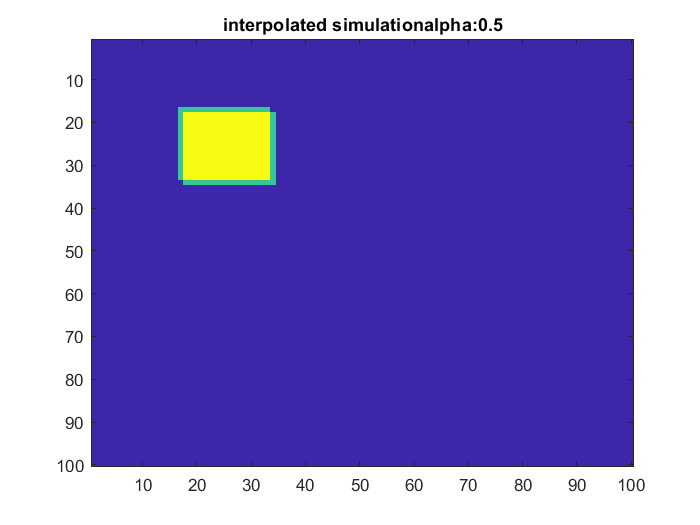

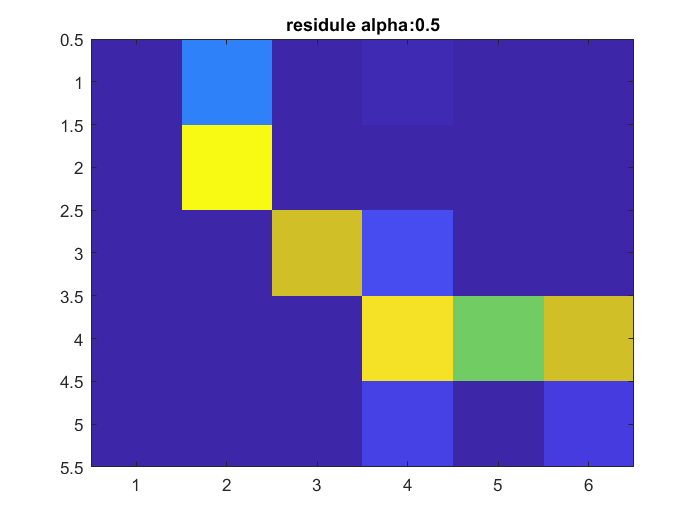

c = 0.6290

c = 1.3940

c = 1.1718

c = 1.0509

c = 0.9737

c = 0.6195

c = 0.6202

c = 0.9240

c = 0.8533

c = 0.8091

c = 0.6195

c = 0.6195

c = 0.6196

c = 1.0305

c = 0.9624

c = 0.6195

c = 0.6195

c = 0.6195

c = 0.8238

c = 0.9817

c = 1.4084

c = 1.0629

c = 0.9287

c = 0.8569

c = 0.8121

c = 0.6195

c = 0.6195

c = 0.9237

c = 0.8530

c = 0.8089

c = 0.6195

c = 0.6195

c = 0.6195

c = 1.0304

c = 1.0912

c = 0.6195

c = 0.6195

c = 0.6195

c = 0.6285

c = 0.8429

c = 1.4084

c = 1.0629

c = 0.9287

c = 0.8569

c = 0.8121

c = 0.6290

c = 1.6971

c = 1.3871

c = 1.2239

c = 1.1198

c = 0.6195

c = 0.6195

c = 0.6195

c = 1.0304

c = 1.0912

c = 0.6195

c = 0.6195

c = 0.6195

c = 0.6285

c = 0.8429

c = 1.4084

c = 1.0629

c = 0.9287

c = 0.8569

c = 0.8121

c = 0.6290

c = 1.6971

c = 1.3871

c = 1.2239

c = 1.1198

c = 0.6195

c = 0.6195

c = 0.9237

c = 0.8530

c = 0.8089

c = 0.6195

c = 0.6195

c = 0.6195

c = 0.6285

c = 0.8429

c = 1.4084

c = 1.0629

c = 0.9287

c = 0.8569

c = 0.8121

c = 0.6290

c = 1.6971

c = 1.3871

c = 1.2239

c = 1.1198

c = 0.6195

c = 0.6195

c = 0.9237

c = 0.8530

c = 0.8089

c = 0.6195

c = 0.6195

c = 0.6195

c = 1.0304

c = 1.0912

alpha = 1

Xhat =     1.0095    0.3852    1.0000    0.0218         0    0.0000
    0.9634    0.6148    0.0000    0.0001         0         0
         0    0.0000    0.0000    0.1771         0         0
         0         0    0.0000    0.6355       NaN    1.0000
         0    0.0000    0.0000    0.1654       NaN    0.0000


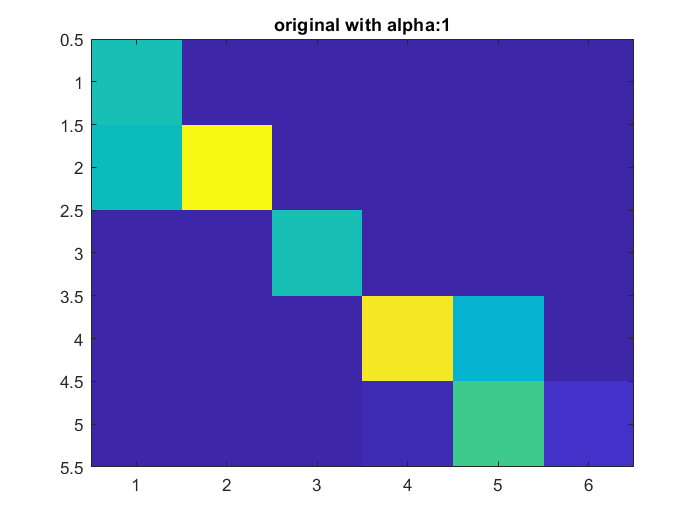

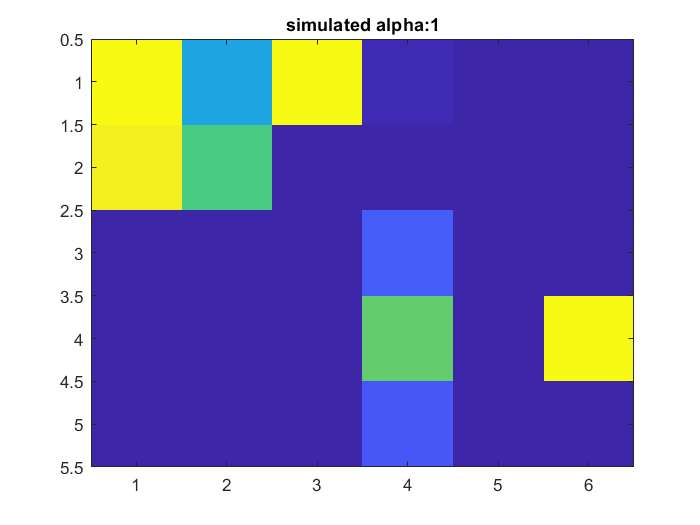

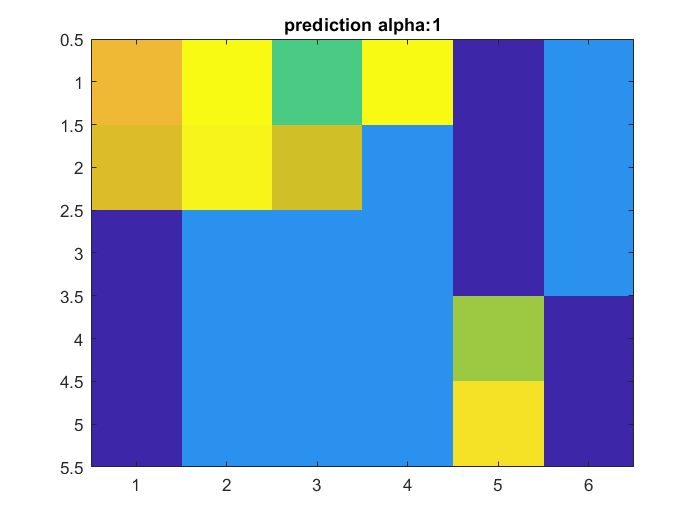

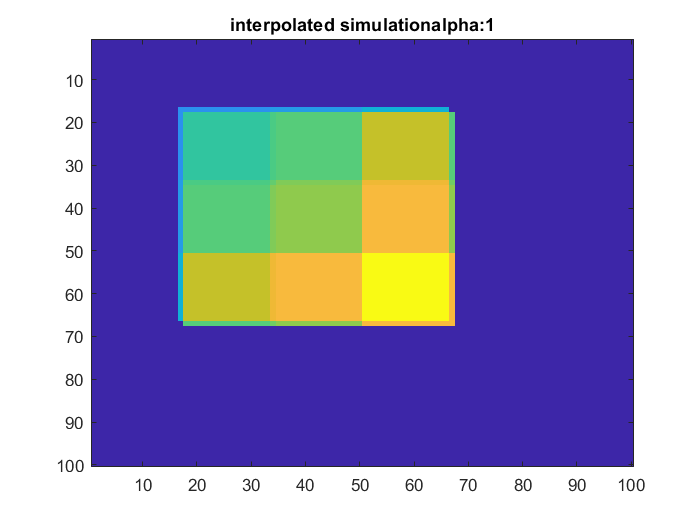

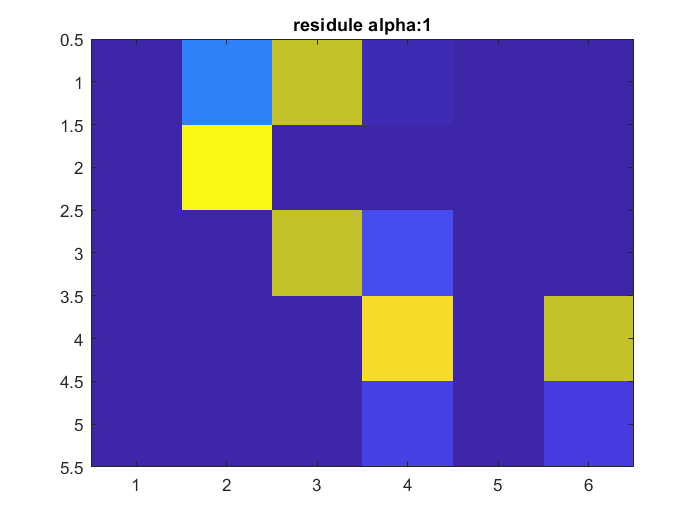

c = 0.6290

c = 1.3940

c = 1.1718

c = 1.0509

c = 0.9737

c = 0.6195

c = 0.6202

c = 0.9240

c = 0.8533

c = 0.8091

c = 0.6195

c = 0.6195

c = 0.6196

c = 1.0305

c = 0.9624

c = 0.6195

c = 0.6195

c = 0.6195

c = 0.8238

c = 0.9817

c = 1.4084

c = 1.0629

c = 0.9287

c = 0.8569

c = 0.8121

c = 0.6195

c = 0.6195

c = 0.9237

c = 0.8530

c = 0.8089

c = 0.6195

c = 0.6195

c = 0.6195

c = 1.0304

c = 1.0912

c = 0.6195

c = 0.6195

c = 0.6195

c = 0.6285

c = 0.8429

c = 1.4084

c = 1.0629

c = 0.9287

c = 0.8569

c = 0.8121

c = 0.6290

c = 1.6971

c = 1.3871

c = 1.2239

c = 1.1198

c = 0.6195

c = 0.6195

c = 0.6195

c = 1.0304

c = 1.0912

c = 0.6195

c = 0.6195

c = 0.6195

c = 0.6285

c = 0.8429

c = 1.4084

c = 1.0629

c = 0.9287

c = 0.8569

c = 0.8121

c = 0.6290

c = 1.6971

c = 1.3871

c = 1.2239

c = 1.1198

c = 0.6195

c = 0.6195

c = 0.9237

c = 0.8530

c = 0.8089

c = 0.6195

c = 0.6195

c = 0.6195

c = 0.6285

c = 0.8429

c = 1.4084

c = 1.0629

c = 0.9287

c = 0.8569

c = 0.8121

c = 0.6290

c = 1.6971

c = 1.3871

c = 1.2239

c = 1.1198

c = 0.6195

c = 0.6195

c = 0.9237

c = 0.8530

c = 0.8089

c = 0.6195

c = 0.6195

c = 0.6195

c = 1.0304

c = 1.0912

alpha = 1.5000

Xhat =     1.0095    0.4033    1.0000    0.0218         0    0.0000
    0.9634    0.5966    0.0000    0.0001         0         0
         0    0.0000    0.0000    0.1769         0         0
         0         0    0.0000    0.6351       NaN    1.0000
         0    0.0000    0.0000    0.1660       NaN    0.0000


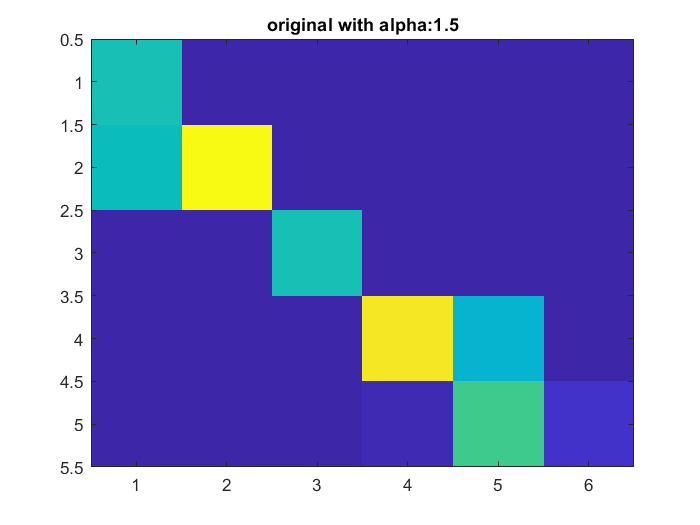

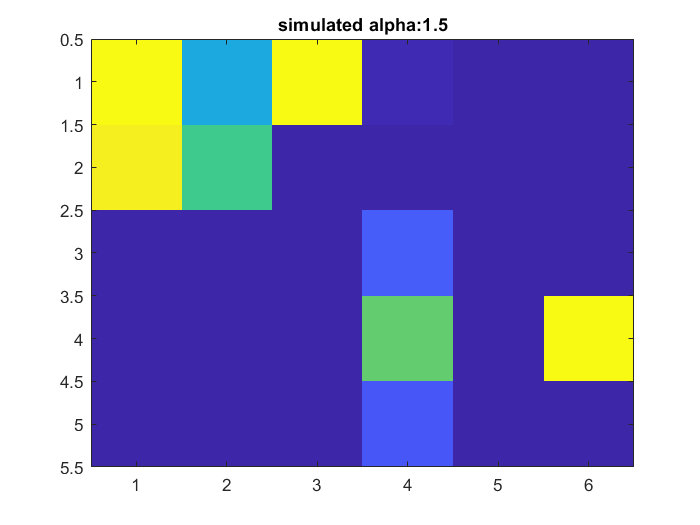

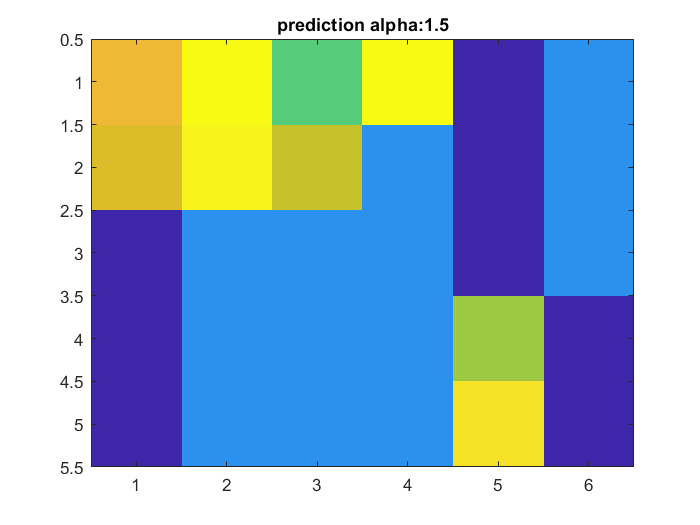

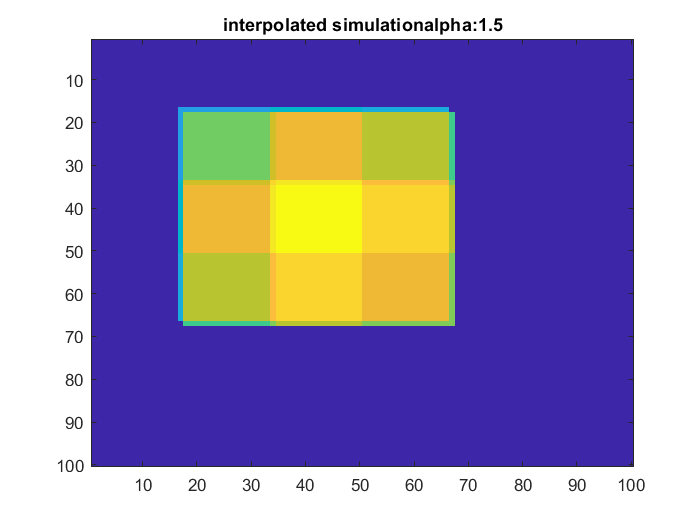

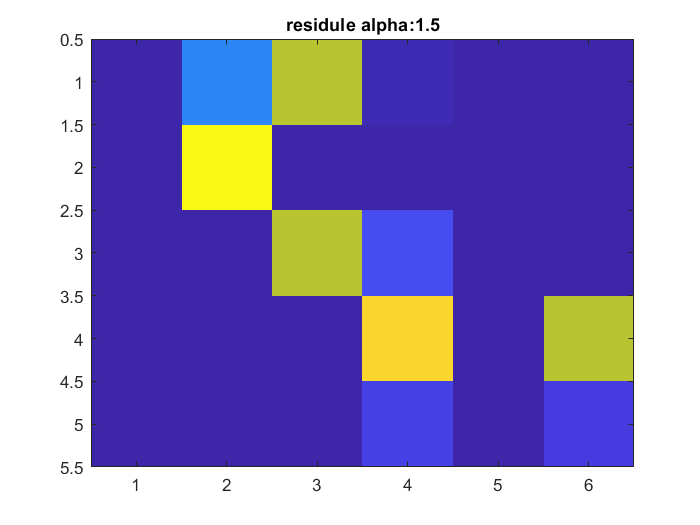

c = 0.6290

c = 1.3940

c = 1.1718

c = 1.0509

c = 0.9737

c = 0.6195

c = 0.6202

c = 0.9240

c = 0.8533

c = 0.8091

c = 0.6195

c = 0.6195

c = 0.6196

c = 1.0305

c = 0.9624

c = 0.6195

c = 0.6195

c = 0.6195

c = 0.8238

c = 0.9817

c = 1.4084

c = 1.0629

c = 0.9287

c = 0.8569

c = 0.8121

c = 0.6195

c = 0.6195

c = 0.9237

c = 0.8530

c = 0.8089

c = 0.6195

c = 0.6195

c = 0.6195

c = 1.0304

c = 1.0912

c = 0.6195

c = 0.6195

c = 0.6195

c = 0.6285

c = 0.8429

c = 1.4084

c = 1.0629

c = 0.9287

c = 0.8569

c = 0.8121

c = 0.6290

c = 1.6971

c = 1.3871

c = 1.2239

c = 1.1198

c = 0.6195

c = 0.6195

c = 0.6195

c = 1.0304

c = 1.0912

c = 0.6195

c = 0.6195

c = 0.6195

c = 0.6285

c = 0.8429

c = 1.4084

c = 1.0629

c = 0.9287

c = 0.8569

c = 0.8121

c = 0.6290

c = 1.6971

c = 1.3871

c = 1.2239

c = 1.1198

c = 0.6195

c = 0.6195

c = 0.9237

c = 0.8530

c = 0.8089

c = 0.6195

c = 0.6195

c = 0.6195

c = 0.6285

c = 0.8429

c = 1.4084

c = 1.0629

c = 0.9287

c = 0.8569

c = 0.8121

c = 0.6290

c = 1.6971

c = 1.3871

c = 1.2239

c = 1.1198

c = 0.6195

c = 0.6195

c = 0.9237

c = 0.8530

c = 0.8089

c = 0.6195

c = 0.6195

c = 0.6195

c = 1.0304

c = 1.0912

alpha = 2

Xhat =     1.0095    0.4191    1.0000    0.0218         0    0.0000
    0.9634    0.5809    0.0000    0.0001         0         0
         0    0.0000    0.0000    0.1768         0         0
         0         0    0.0000    0.6349       NaN    1.0000
         0    0.0000    0.0000    0.1664       NaN    0.0000


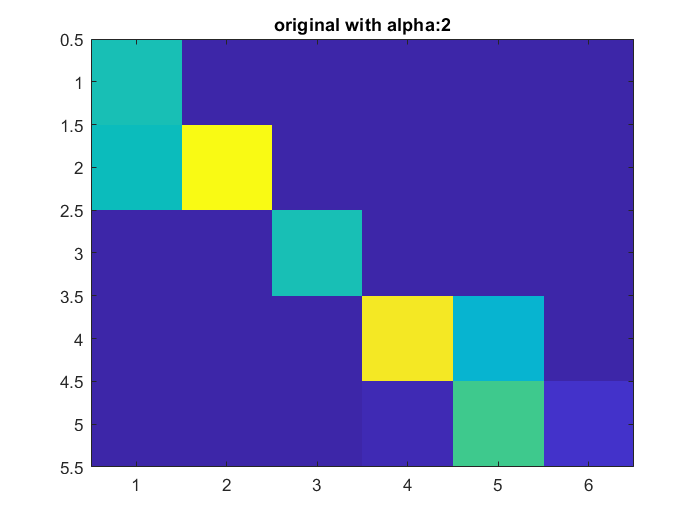

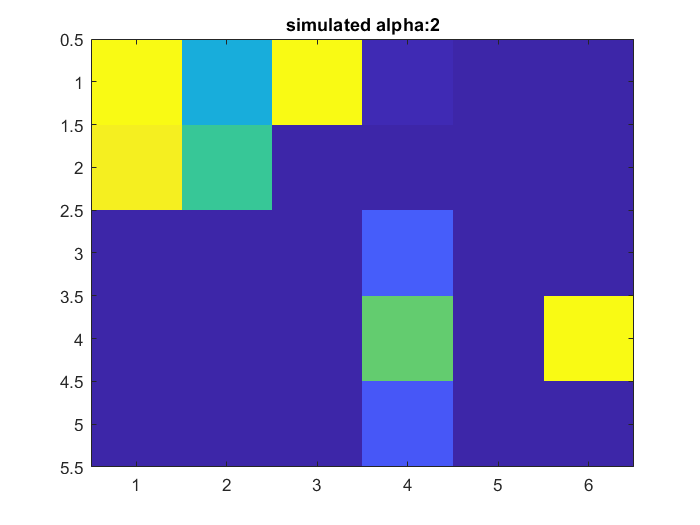

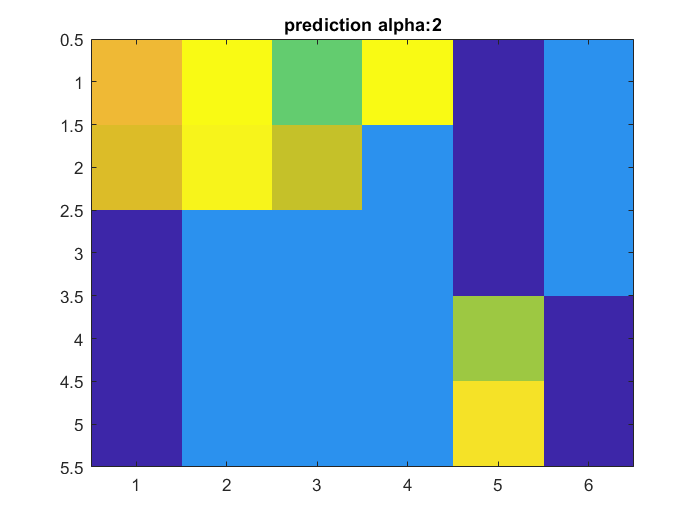

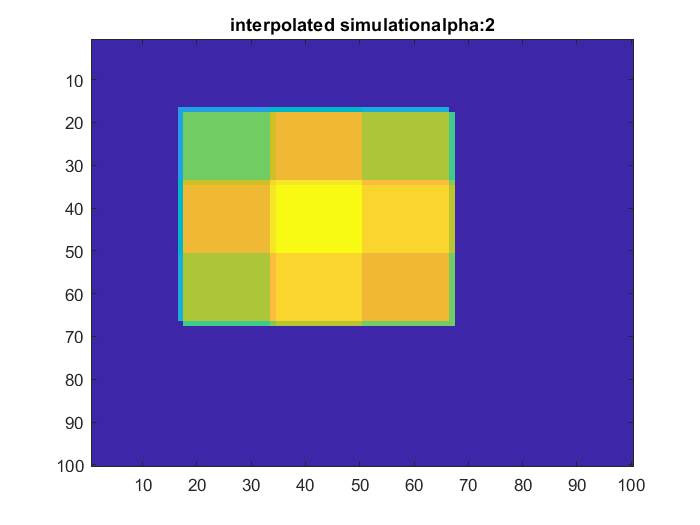

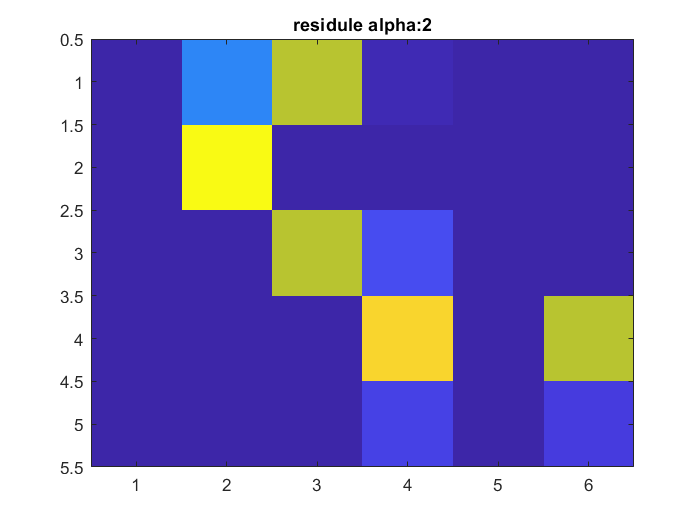

% determine k and eps with deterministic model 
W = exp(-w0.^2/2)/sqrt(2*pi*1);
mu = mean(P(1,:));
sigma = var(P(1,:));
B = exp(mu-sigma^2*t/2+sigma*W);
W1 = exp(-P(2,:).^2/2)/sqrt(2*pi*1);
mu1 = mean(P(2,:));
sigma1 = var(P(2,:));
B1 = exp(mu1-sigma1^2*t/2+sigma1*W1);
k = sigma*B./W-1;
% W1 -W = eps1*W1*(D(1,:)-k*W(1,:))+sigma1*W1*(B1-B)
eps1 = (W1-W-sigma1*W1.*(B1-B))./W1./(D(1,:)-k.*W(1,:));
eps = mean(eps1);
% learning rate
delta = 0.1;
% learning rate for potential function of cost
gamma = 100;
% initial threshold 
Sum = 100;
sc = 1;
% optimize the cost and predict
for alpha = [0.5,1,1.5,2]
    for i = 1:M-1
        if i ==1
            for j = 2:M-1
                for t = 1:5
                    if t == 1
                        mui = P(j,1);
                        vari = P(j,1);
                        c = mui - beta*log(-log(normpdf(mui)))+const
                        %cost 
                        W = exp(-P(i,:).^2/2)/sqrt(2*pi*1);
                        V(i,t) = -eps*(1/alpha*sum(O(i,1).*log(exp(alpha*P(j,1)-beta*c))))+sum(k*exp(P(j,1))); 
                        %brownian
                        b(i,t) = exp(mui-vari*t/2+std(P(j,1:t))*W(t));
                    else
                        mui = mean(P(j,1:t));
                        vari = var(P(j,1:t));
                        c = mui - beta*log(-log(normpdf(mui)))+const
                        W = exp(-P(j,:).^2/2)/sqrt(2*pi*1);
                        V(i,t) = sum(-eps*(1/alpha*sum(O(i,t)*log(sum(exp(alpha*P(j,1:t)-beta*c))))+k(j)*sum(exp(P(j,1:t)))));
                        b(i,t) = exp(mui-vari*t/2+std(P(j,t))*W(t));
                    end       
                end
            end
            dX(i,:)=(-V(i,:)+sqrt(vari)*b(i,:));
        elseif i<M-1
            for j  = [1:i-1,i+1:M-1]
                for t = 1:5
                    if t == 1
                        mui = P(j,1);
                        vari = P(j,1:t);
                        c = mui - beta*log(-log(normpdf(mui)))+const
                        W = exp(-P(j,:).^2/2)/sqrt(2*pi*1);
                        V(i,t) = -eps*(1/alpha*(O(i,t).*log(exp(alpha*P(j,t)-beta*c))))+k(j)*exp(P(j,t)); 
                        b(i,t) = exp(mui-vari*t/2+std(P(j,1:t))*W(t));
                    else
                        mui = mean(X(j,1:t));
                        vari = var(X(j,1:t));
                        c = mui - beta*log(-log(normpdf(mui)))+const
                        W = exp(-P(j,:).^2/2)/sqrt(2*pi*1);
                        V(i,t) = -eps*(1/alpha*(O(i,t).*log(exp(alpha*P(j,t)-beta*c))))+k(j)*exp(P(j,t)); 
                        b(i,t) = exp(mui-vari*t/2+std(P(j,1:t))*W(t));
                    end       
                end            
            end
        elseif i == M-1
            for j  = [1:i-1]
                for t = 1:5
                    if t == 1
                        mui = P(j,1);
                        vari = P(j,1:t);
                        c = mui - beta*log(-log(normpdf(mui)))+const
                        W = exp(-P(j,:).^2/2)/sqrt(2*pi*1);
                        V(i,t) = -eps*(1/alpha*(O(i-1,t).*log(exp(alpha*P(j,t)-beta*c))))+k(j)*exp(P(j,t)); 
                        b(i,t) = exp(mui-vari*t/2+std(P(j,1:t))*W(t));
                    else
                        mui = mean(X(j,1:t));
                        vari = var(X(j,1:t));
                        c = mui - beta*log(-log(normpdf(mui)))+const
                        W = exp(-P(j,:).^2/2)/sqrt(2*pi*1);
                        V(i,t) = -eps*(1/alpha*(O(i-1,t).*log(exp(alpha*P(j,t)-beta*c))))+k(j)*exp(P(j,t)); 
                        b(i,t) = exp(mui-vari*t/2+std(P(j,1:t))*W(t));
                    end       
                end            
            end
            %predict the stochastic dynamics
            dX(i,:)=(-V(i,:)+sqrt(vari)*b(i,:));
        end
    end
    Xhat = X;%What = exp(Xhat);
    %prediction simulated
    Y = Xhat;
    Yhat = zeros(5,100,6);
    %Bayes prediiction
    for dt = 1:5
        for steps = 1: 100
    %    Xhat(1+dt,:) = X(dt,:) + dX(dt,:)/sum(dX(dt,:));
            Xhat(:,1+dt) = dX(:,dt).*exp(-gamma*V(:,dt))+P(1+dt,:)' + dX(:,dt)./sum(dX(:,dt));
            Xhat(Xhat(:,1+dt)<0,1+dt) = 0.000001;
            %normalization
            Xhat(:,1+dt) = Xhat(:,1+dt)./sum(Xhat(:,1+dt));
            if sum(sum(abs(Xhat(:,1+dt) - P(1+dt,:)'))) < Sum
                Y(:,1+dt) = Xhat(:,dt) + normpdf(Xhat(:,dt),0,1); 
                Mu = mean(Xhat(:,dt));
                Sigma = std(Xhat(:,dt));
                Yhat(:,steps,1+dt) = normpdf(Xhat(:,dt),Mu,Sigma)+ normpdf(Xhat(:,dt),0,1); 
                Yhat(isnan(Yhat(:,steps,1+dt)),steps, 1+dt)  = 0 ;              
            end
        end
    end
    display(alpha)
    display(Xhat)
 
    figure,
    imagesc(X);
    title(['original with alpha:',num2str(alpha)])
    figure,
    imagesc(Xhat);
    title(['simulated alpha:',num2str(alpha)])
    figure,
    imagesc(Y);
    title(['prediction alpha:',num2str(alpha)])
    Interp = reshape(Yhat(sc,:,:),6,100);
    figure,
    imagesc(sqrt(Interp'*Interp));
    title(['interpolated simulationalpha:',num2str(alpha)])
    figure,
    imagesc(abs(Xhat-X));
    title(['residule alpha:',num2str(alpha)])
    sc = sc +1;
end

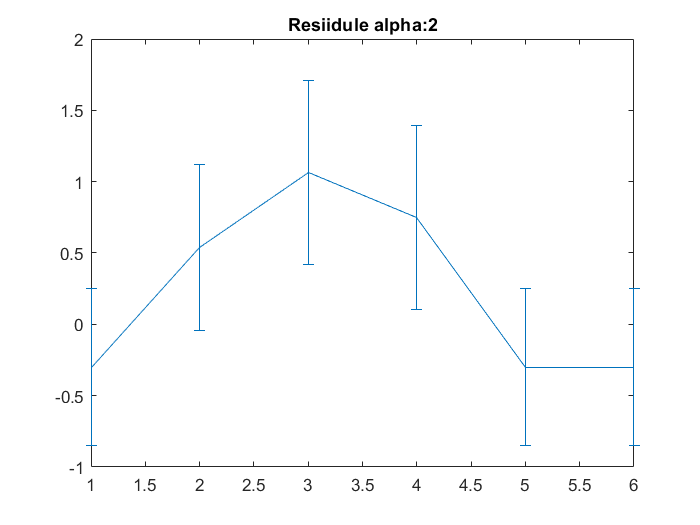

%best at alpha = 2
meanRes = zeros(100,6);
stdRes = meanRes;
for steps = 1:100
    meanRes(steps,:) = mean(mean(Yhat(:,steps,:)-X));
    stdRes(steps,:) = mean(std(Yhat(:,steps,:)-X));   
end
CV = stdRes./meanRes;

figure,
errorbar(meanRes(1,:),stdRes(1,:));
title(['Resiidule alpha:',num2str(alpha)])

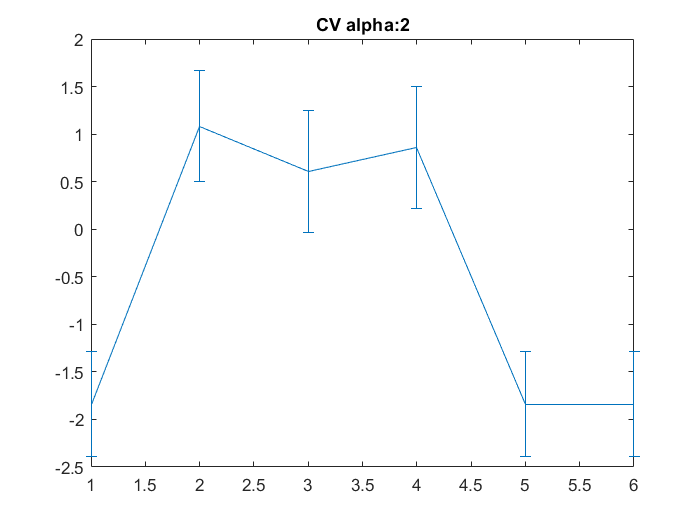


figure,
errorbar(CV(1,:),stdRes(1,:));
title(['CV alpha:',num2str(alpha)])